## Assigment-Q2

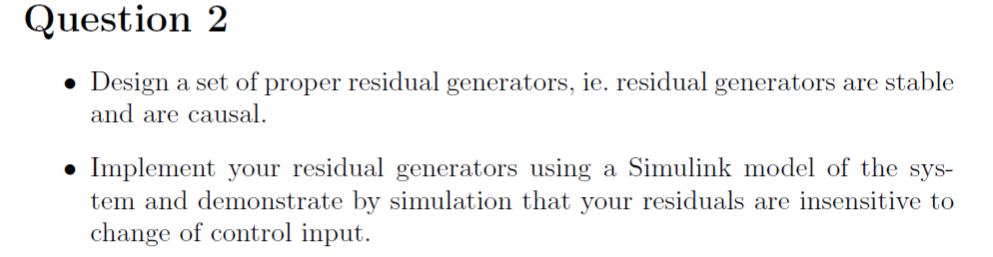


clear all;
close all;
clc;
load('ECP_values.mat');


% Physical system parameters
J_1 = ECP_values(1);            % Disk 1 inertia kgm^2
J_2 = ECP_values(2);            % Disk 2 inertia kgm^2
J_3 = ECP_values(3);            % Disk 3 inertia kgm^2
k_1 = ECP_values(4);            % Shaft 1-2 stiffness Nm/rad
k_2 = ECP_values(5);            % Shaft 2-3 stiffness Nm/rad
b_1 = mean(ECP_values([6 7]));  % Disk 1 damping and friction Nms/rad
b_2 = mean(ECP_values([8 9]));  % Disk 2 damping and friction Nms/rad
b_3 = mean(ECP_values([10 11]));% Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                    % Threshold angular velocity rad/s

%Added parameters:
tau1=100;
tau2=100;

% The system states are [theta_1;omega_1;theta_2;omega_2;theta_3;omega_3]
x_0 = [0;0;0;0;0;0];            % Initial conditions

T_s = 0.004;                    % Sampling period
sigma_meas = deg2rad(0.0056)*[1;1;1]; % Measurements noise

%% GLR
f_m = [0;-0.125;0]; % Sensor fault vector (added to [y1;y2;y3])

%% State space representation

C = [1 0 0 0 0 0;
    0 0 1 0 0 0;
    0 0 0 0 1 0];

% Simulation
simTime = 700;       % Simulation duration in seconds
f_m_time = 8.5;     % Sensor fault occurence time


Conclusion:

-Both residuals have first and second order derivatives. Therefore, introduce inestability on the system. To compensate, it is necessary to introduce a filter to each of them, with same order as the second order derivatives.

-H0: No fault presence. "f_y" step is 0. Both residuals have 0 mean value in spite of the disturbances and input that are introduced in the system. Therefore, insensitive of change in control input.

%H0: residual plot

switch_fault=0;
sim('Q2_Simulink');

figure
plot(r.time,r.signals.values(:,1),r.time,r.signals.values(:,2))
title('Residuals in absence of faults: H0')
ylabel('r')
xlabel('Time(s)')
legend('r1','r2')


-H1: Fault presence. "f_y" step is f_m = [0;-0.125;0]; There is a fault in y2. Therefore, residuals change from 0 mean, to non-zero mean value when the faul occurs: f_m_time = 8.5; 

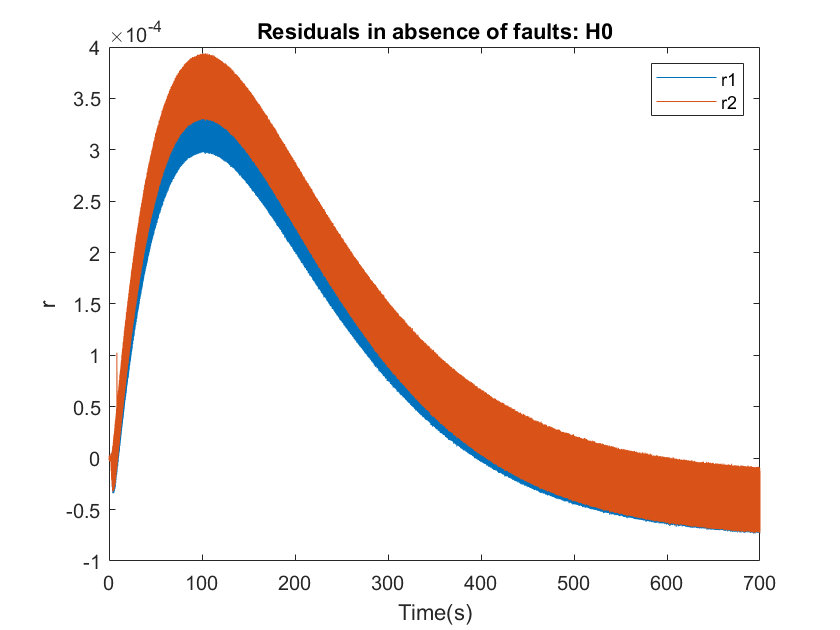

%H1: residual plot

switch_fault=1;
sim('Q2_Simulink');

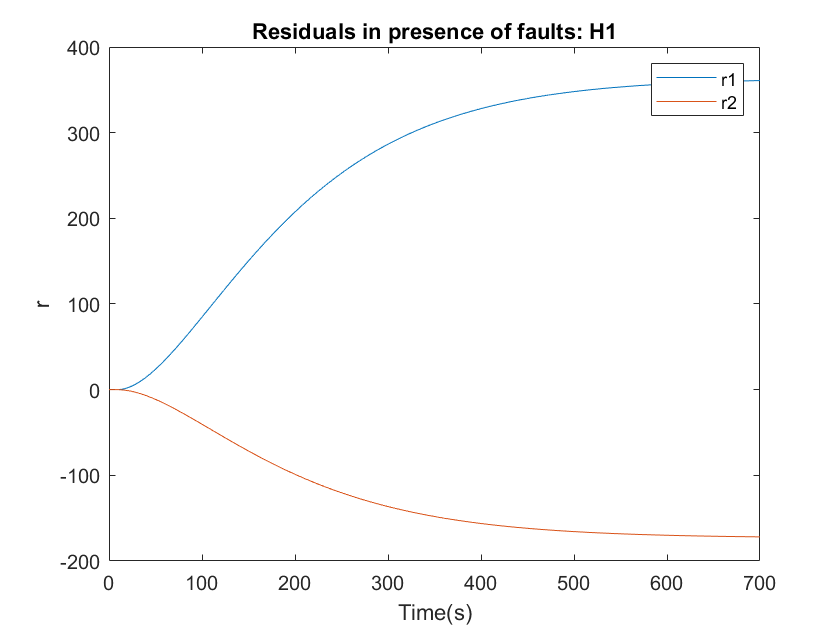


figure
plot(r.time,r.signals.values(:,1),r.time,r.signals.values(:,2))
title('Residuals in presence of faults: H1')
ylabel('r')
xlabel('Time(s)')
legend('r1','r2')

-The ouput of the system "y" has an unstable response. It makes sense, since the outputs are theta_1,theta_2, theta_3,incremental position encoders for each disc. Input "u" is a torque on the bottom disc that will make the encoders grow unbounded.

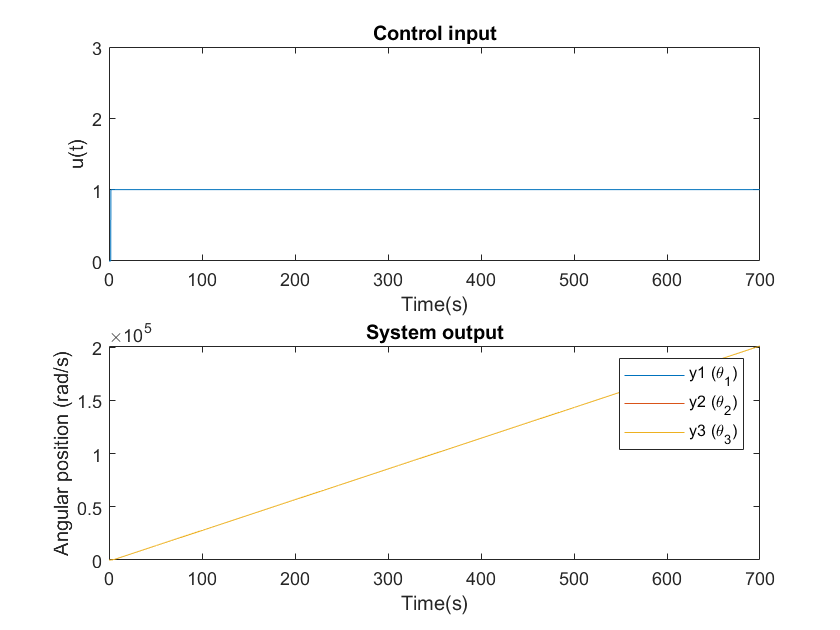

%plot output: incremental position encoders

figure
subplot(2,1,1)
plot(u.time,u.signals.values)
title('Control input')
ylabel('u(t)')
xlabel('Time(s)')
ylim([0 3])

subplot(2,1,2)
plot(y.time,y.signals.values(:,1),y.time,y.signals.values(:,2),y.time,y.signals.values(:,3))
title('System output')
ylabel('Angular position (rad/s)')
xlabel('Time(s)')
legend('y1 (\theta_1)','y2 (\theta_2)','y3 (\theta_3)')